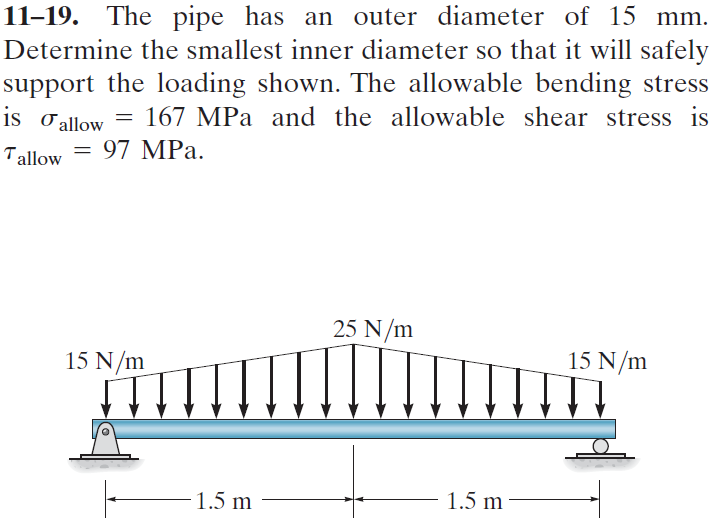

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-19P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-19P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
w1 = findpoly(1, 'thru', [0 -15*u.N/u.m], 'thru', [1.5*u.m -25*u.N/u.m]);
w2 = findpoly(1, 'thru', [1.5*u.m -25*u.N/u.m], 'thru', [3*u.m -15*u.N/u.m]);
Di_min = default_struct('bending', 'shear', 'limit');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 3*u.m);
b = b.add('distributed', 'force', w1, [0 1.5]*u.m);
b = b.add('distributed', 'force', w2, [1.5 3]*u.m, [false true]);
b.L = 3*u.m;

# section properties

Do = 15*u.mm;
Di = sym('Di');
Ro = Do/2;
Ri(Di) = Di/2;
yc = 4/(3*sympi)*[Ro; Ri; -Ri; -Ro];
Ac = sympi/2*[Ro^2; -Ri^2; -Ri^2; Ro^2];
Ic = (sympi/8-8/(9*sympi))*[Ro^4; -Ri^4; -Ri^4; Ro^4];
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{3200000000\,x\,\left(16\,x^{4}+180\,x^{3}\,m-1440\,x^{2}\,m^{2}+6885\,m^{4}\right)}{9\,\text{E}\,\pi \,\left(40000\,{\mathrm{Di}}^{2}+9\,m^{2}\right)\,\left(200\,\mathrm{Di}-3\,m\right)\,\left(200\,\mathrm{Di}+3\,m\right)}\,\frac{N}{m^{2}} & \text{ if }x\leq \frac{3}{2}\,m\\ -\frac{3200000000\,\left(x-3\,m\right)\,\left(16\,x^{4}-372\,x^{3}\,m+1044\,x^{2}\,m^{2}+2052\,x\,m^{3}+81\,m^{4}\right)}{9\,\text{E}\,\pi \,\left(40000\,{\mathrm{Di}}^{2}+9\,m^{2}\right)\,\left(200\,\mathrm{Di}-3\,m\right)\,\left(200\,\mathrm{Di}+3\,m\right)}\,\frac{N}{m^{2}} & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{16000000000\,\left(2\,x-3\,m\right)\,\left(-8\,x^{3}-84\,x^{2}\,m+306\,x\,m^{2}+459\,m^{3}\right)}{9\,\text{E}\,\pi \,\left(40000\,{\mathrm{Di}}^{2}+9\,m^{2}\right)\,\left(200\,\mathrm{Di}-3\,m\right)\,\left(200\,\mathrm{Di}+3\,m\right)}\,\frac{N}{m^{2}} & \text{ if }x\leq \frac{3}{2}\,m\\ -\frac{16000000000\,\left(2\,x-3\,m\right)\,\left(8\,x^{3}-156\,x^{2}\,m+414\,x\,m^{2}+405\,m^{3}\right)}{9\,\text{E}\,\pi \,\left(40000\,{\mathrm{Di}}^{2}+9\,m^{2}\right)\,\left(200\,\mathrm{Di}-3\,m\right)\,\left(200\,\mathrm{Di}+3\,m\right)}\,\frac{N}{m^{2}} & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(4\,x^{2}+27\,x\,m-108\,m^{2}\right)}{18}\,\frac{N}{m^{2}} & \text{ if }x\leq \frac{3}{2}\,m\\ \frac{5\,\left(x-3\,m\right)\,\left(4\,x^{2}-51\,x\,m+9\,m^{2}\right)}{18}\,\frac{N}{m^{2}} & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(x+6\,m\right)\,\left(2\,x-3\,m\right)}{3}\,\frac{N}{m^{2}} & \text{ if }x\leq \frac{3}{2}\,m\\ \frac{5\,\left(x-9\,m\right)\,\left(2\,x-3\,m\right)}{3}\,\frac{N}{m^{2}} & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(4\,x+9\,m\right)}{3}\,\frac{N}{m^{2}} & \text{ if }x\leq \frac{3}{2}\,m\\ \frac{5\,\left(4\,x-21\,m\right)}{3}\,\frac{N}{m^{2}} & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 30\,N\\ \mathrm{Rb} & 30\,N \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

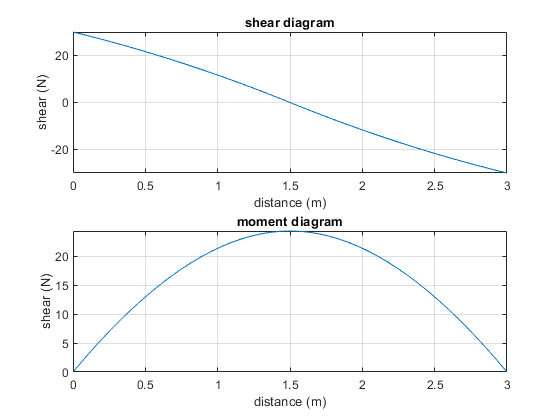

beam.shear_moment(m, v, [0 b.L], {'N' 'm'});

# maximum loads

M_max = m(b.L/2);
M_max_vpa = vpa(M_max) %#ok<NASGU> 

$$M\_max\_vpa = 24.375\,N\,m$$

V_max = v(0)

$$V\_max = 30\,N$$

# maximum stresses

C = Ro;
b.I = simplify(rewrite(b.I, u.mm));
sigma_max = rewrite(M_max*C/b.I, [u.MPa u.mm])

$$sigma\_max(Di) = \frac{11700000}{\pi \,\left(50625\,{\mathrm{mm}}^{4}-{\mathrm{Di}}^{4}\right)}\,\mathrm{MPa}\,{\mathrm{mm}}^{4}$$

Q_max(Di) = simplify(sum(index(Qn, 1:2)));
t_min(Di) = Do-Di;
tau_max = rewrite(V_max*Q_max/(b.I*t_min), [u.MPa u.mm])

$$tau\_max(Di) = -\frac{1920\,\left(\frac{1125}{4}\,{\mathrm{mm}}^{3}-\frac{{\mathrm{Di}}^{3}}{12}\right)}{\pi \,\left(50625\,{\mathrm{mm}}^{4}-{\mathrm{Di}}^{4}\right)\,\left(\mathrm{Di}-15\,\mathrm{mm}\right)}\,\mathrm{MPa}\,{\mathrm{mm}}^{2}$$

# minimum inner diameter

sigma_allow = 167*u.MPa;
tau_allow = 97*u.MPa;
assume(0 < Di & Di < Do);
Di_min.bending = solve(sigma_max == sigma_allow);
Di_min.bending = simplify(Di_min.bending);
Di_min_bending = vpa(Di_min.bending, 4) %#ok<NASGU> 

$$Di\_min\_bending = 12.97\,\mathrm{mm}$$

Di_min.shear = solve(tau_max == tau_allow);
Di_min.shear = simplify(separateUnits(Di_min.shear))*u.mm;
Di_min_shear = vpa(Di_min.shear, 4) %#ok<NASGU> 

$$Di\_min\_shear = 14.97\,\mathrm{mm}$$

Di_min_vals = [Di_min.bending Di_min.shear];
loc = (sigma_max(Di_min_vals) <= sigma_allow) & ...
      (tau_max(Di_min_vals) <= tau_allow);
Di_min.limit = Di_min_vals(isAlways(loc));
Di_min_limit = vpa(Di_min.limit, 4) %#ok<NASGU> 

$$Di\_min\_limit = 12.97\,\mathrm{mm}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;
clear M_max_vpa;
clear Di_min_bending Di_min_shear Di_min_vals loc Di_min_limit;